clc
clear

system("g++ main.cpp -o main.exe -O2");
system("main.exe");

As = readmatrix("A_Sparse.txt");
b = readmatrix("b_vector.txt");
b = b(:,2);
row = As(:,1);
col = As(:,2);
data = As(:,3);

A = sparse(row,col,data);
% spy(A)

sol=A\b;

len = length(sol);
ux_ = sol(1:len/2);
uy_ = sol(len/2+1:len);

d = readmatrix("data.txt", ...
    "NumHeaderLines",0);
h = readmatrix("header.txt", ...
    "NumHeaderLines",0);
x_ = d(:,1);
y_ = d(:,2);

xmin = min(x_);
xmax = max(x_);
ymin = min(y_);
ymax = max(y_);

nx = h(2,1);
ny = h(3,1);
dx = h(4,1);
dy = h(5,1);

for i = 0:ny-1
    for j = 0:nx-1
        ux(i+1,j+1) = ux_(i + ny * j + 1); %#ok
        uy(i+1,j+1) = uy_(i + ny * j + 1); %#ok
        x(i+1,j+1) = x_(i + ny * j + 1); %#ok
        y(i+1,j+1) = y_(i + ny * j + 1); %#ok
    end
end

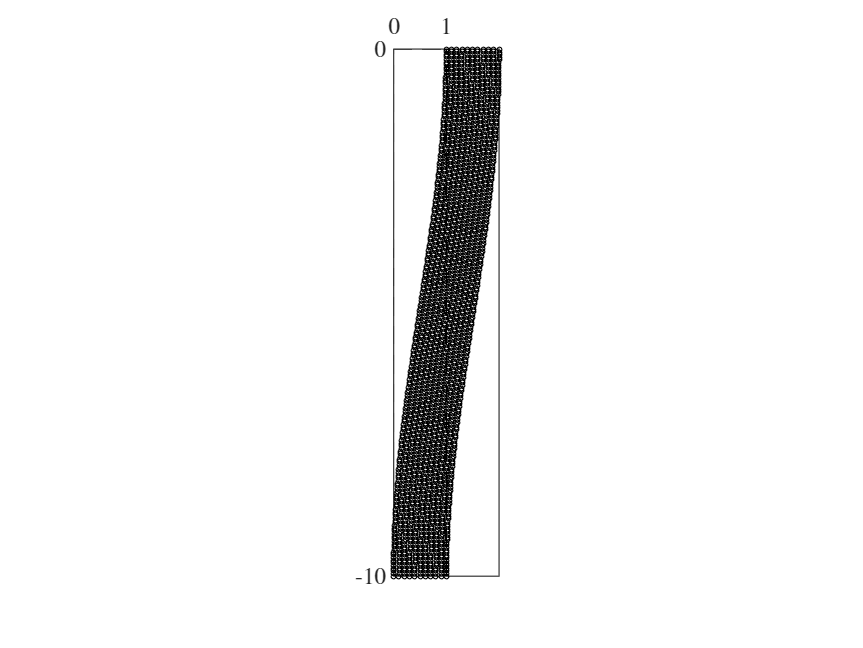

figure();
xdash = x + ux;
ydash = y + uy;
midline_x = xdash(:,round(size(ux,2)/2));
midline_y = ydash(:,round(size(uy,2)/2));
xdash = reshape(xdash,[],1);
ydash = reshape(ydash,[],1);
plot(xdash,ydash,'ko','MarkerSize',2);
hold on
plot([min(x(:)),max(x(:))], ...
    [min(y(:)),min(y(:))],'k--')
plot([min(x(:)),max(x(:))], ...
    [max(y(:)),max(y(:))],'k--')
plot([min(x(:)),min(x(:))], ...
    [min(y(:)),max(y(:))],'k--')
plot([max(x(:)),max(x(:))], ...
    [min(y(:)),max(y(:))],'k--')
hold off
set(gca,'XAxisLocation','top');
axis equal
box on
xlim([min(xdash(:)),max(xdash(:))])
ylim([min(ydash(:)),max(ydash(:))])
xticks([0,max(x(:))])
if (max(y(:)) == 0)
    yticks(fliplr([0,min(y(:))]))
else
    yticks([0,min(y(:))])
end

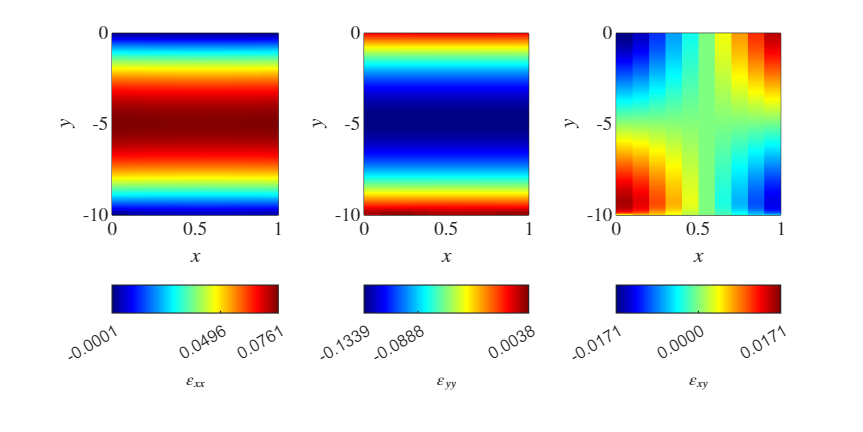

% Rows(Dim1) = Y, Columns(Dim2) = X
[duxdy,e_xx] = gradient(ux,dy,dx);
[e_yy,duydx] = gradient(uy,dy,dx);
e_xy = 0.5*(duxdy + duydx);

e_xx(abs(e_xx)<=1e-10) = 0;
e_yy(abs(e_yy)<=1e-10) = 0;
e_xy(abs(e_xy)<=1e-10) = 0;

E = 68; % [GPa]
nu = 0.33;
sigma_xx = E/(1+nu) * (e_xx + nu/(1-2*nu) * (e_xx + e_yy));
sigma_yy = E/(1+nu) * (e_yy + nu/(1-2*nu) * (e_xx + e_yy));
sigma_xy = E/(1+nu) * (e_xy);

figure("Position",[0,0,600,300])
colormap("jet")
tiledlayout(1,3);
nexttile(1);
surf(x,y,e_xx, ...
    'EdgeColor','none')
xlabel("$x$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
cb = colorbar("southoutside");
cb.Label.String = "$\varepsilon_{xx}$";
cb.Label.Interpreter = "latex";
if (min(e_xx(:)) ~= max(e_xx(:)))
    cb.Ticks = sort([min(e_xx(:)), ...
        max(e_xx(:)),mean(e_xx(:))]);
else
    cb.Ticks = e_xx(1);
end
cb.Ruler.TickLabelFormat = '%.4f';
view([0 90])
box on

nexttile(2);
surf(x,y,e_yy, ...
    'EdgeColor','none')
xlabel("$x$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
cb = colorbar("southoutside");
cb.Label.String = "$\varepsilon_{yy}$";
cb.Label.Interpreter = "latex";
if (min(e_yy(:)) ~= max(e_yy(:)))
    cb.Ticks = sort([min(e_yy(:)), ...
        max(e_yy(:)),mean(e_yy(:))]);
else
    cb.Ticks = e_yy(1);
end
cb.Ruler.TickLabelFormat = '%.4f';
view([0 90])
box on

nexttile(3);
surf(x,y,e_xy, ...
    'EdgeColor','none')
xlabel("$x$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
cb = colorbar("southoutside");
cb.Label.String = "$\varepsilon_{xy}$";
cb.Label.Interpreter = "latex";
if (min(e_xy(:)) ~= max(e_xy(:)))
    cb.Ticks = sort([min(e_xy(:)), ...
        max(e_xy(:)),mean(e_xy(:))]);
else
    cb.Ticks = e_xy(1);
end
cb.Ruler.TickLabelFormat = '%.4f';
view([0 90])
box on

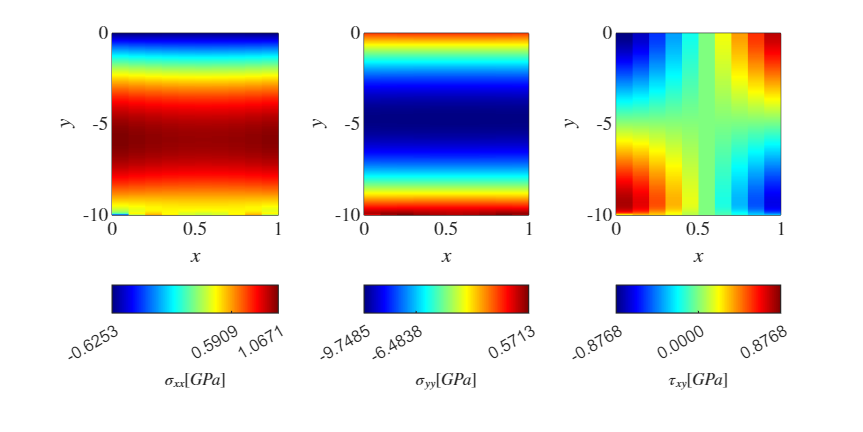


figure("Position",[0,0,600,300])
colormap("jet")
tiledlayout(1,3);
nexttile(1);
surf(x,y,sigma_xx, ...
    'EdgeColor','none')
xlabel("$x$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
cb = colorbar("southoutside");
cb.Label.String = "$\sigma_{xx} [GPa]$";
cb.Label.Interpreter = "latex";
if (min(sigma_xx(:)) ~= max(sigma_xx(:)))
    cb.Ticks = sort([min(sigma_xx(:)), ...
        max(sigma_xx(:)),mean(sigma_xx(:))]);
else
    cb.Ticks = sigma_xx(1);
end
cb.Ruler.TickLabelFormat = '%.4f';
view([0 90])
box on

nexttile(2);
surf(x,y,sigma_yy, ...
    'EdgeColor','none')
xlabel("$x$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
cb = colorbar("southoutside");
cb.Label.String = "$\sigma_{yy} [GPa]$";
cb.Label.Interpreter = "latex";
if (min(sigma_yy(:)) ~= max(sigma_yy(:)))
    cb.Ticks = sort([min(sigma_yy(:)), ...
        max(sigma_yy(:)),mean(sigma_yy(:))]);
else
    cb.Ticks = sigma_yy(1);
end
cb.Ruler.TickLabelFormat = '%.4f';
view([0 90])
box on

nexttile(3);
surf(x,y,sigma_xy, ...
    'EdgeColor','none')
xlabel("$x$","Interpreter","latex")
ylabel("$y$","Interpreter","latex")
cb = colorbar("southoutside");
cb.Label.String = "$\tau_{xy} [GPa]$";
cb.Label.Interpreter = "latex";
if (min(sigma_xy(:)) ~= max(sigma_xy(:)))
    cb.Ticks = sort([min(sigma_xy(:)), ...
        max(sigma_xy(:)),mean(sigma_xy(:))]);
else
    cb.Ticks = sigma_xy(1);
end
cb.Ruler.TickLabelFormat = '%.4f';
view([0 90])
box on

figure()
plot(midline_x,midline_y,'r.')
[ft,s] = fit(midline_x,midline_y,'poly4')

ft =      Linear model Poly4:
     ft(x) = p1*x^4 + p2*x^3 + p3*x^2 + p4*x + p5
     Coefficients (with 95% confidence bounds):
       p1 =     -0.1691  (-3.663, 3.324)
       p2 =       14.62  (0.6247, 28.62)
       p3 =      -42.85  (-63.11, -22.6)
       p4 =       48.21  (35.71, 60.7)
       p5 =      -24.79  (-27.55, -22.04)

s = struct with fields:
           sse: 3.5934
       rsquare: 0.9979
           dfe: 196
    adjrsquare: 0.9978
          rmse: 0.1354


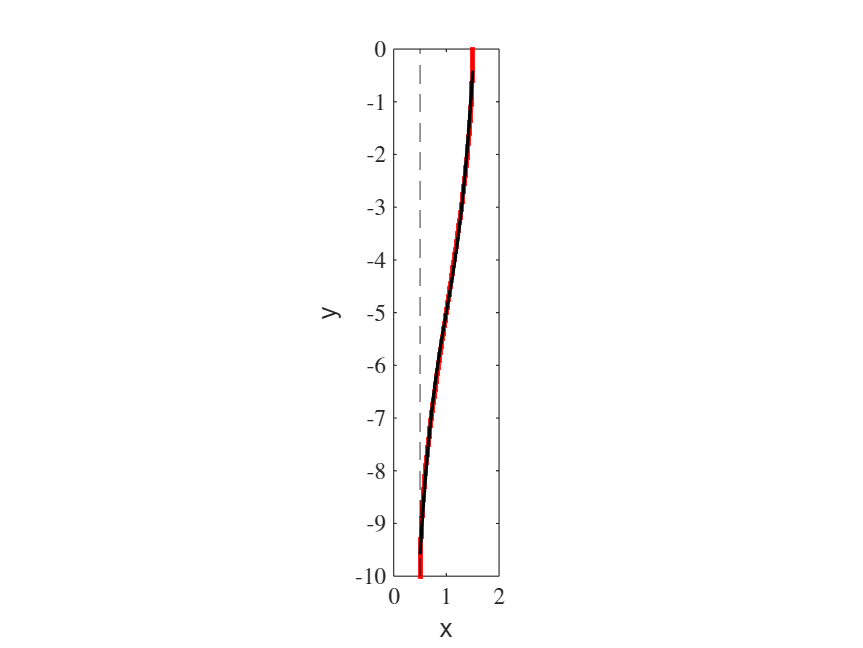

% [ft,s] = fit(midline_x,midline_y, ...
%     "a*x^4 + b*x^3 + c*x^2 + d", ...
%     "StartPoint",[0,0,0,0])
hold on
plot(ft,'k')
xline(xmax/2-xmin/2,'k--')
hold off
axis equal
box on
legend off
xlim([0,max(xdash(:))])
ylim([min(ydash),0])